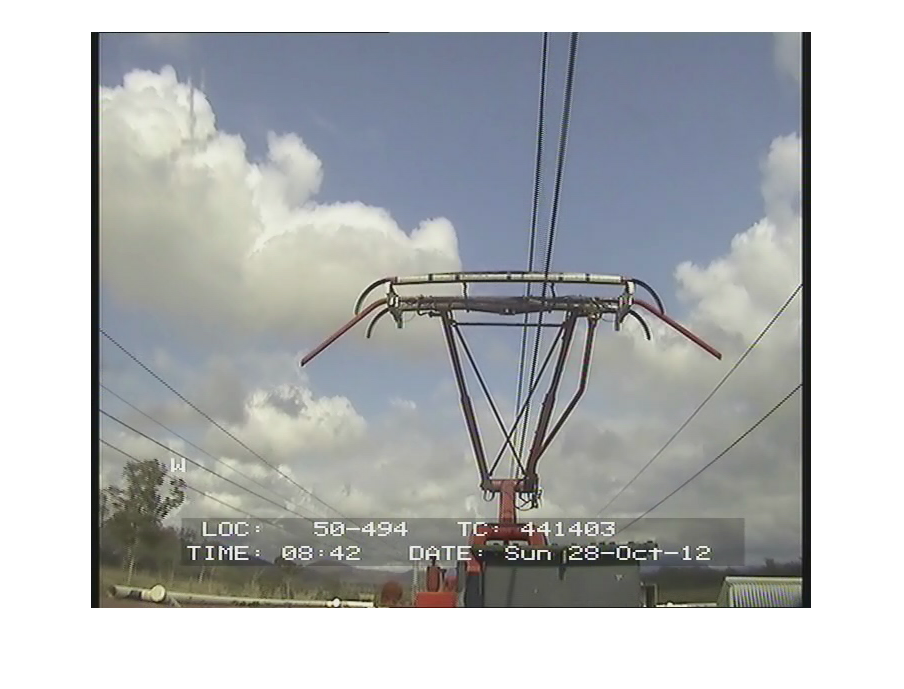

videoReader = VideoReader('Eric_video.avi');
% for i = 1:38
%     videoReader.readFrame();
% end
aCurrentFrame = videoReader.readFrame();
imshow(aCurrentFrame);

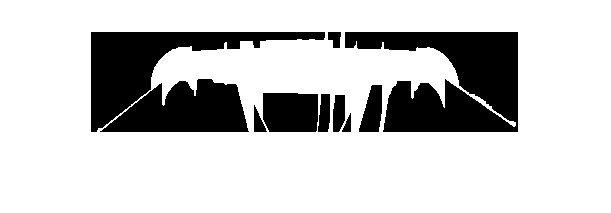

theTemplateImage = imread('pantograph_template.png');
imshow(theTemplateImage);

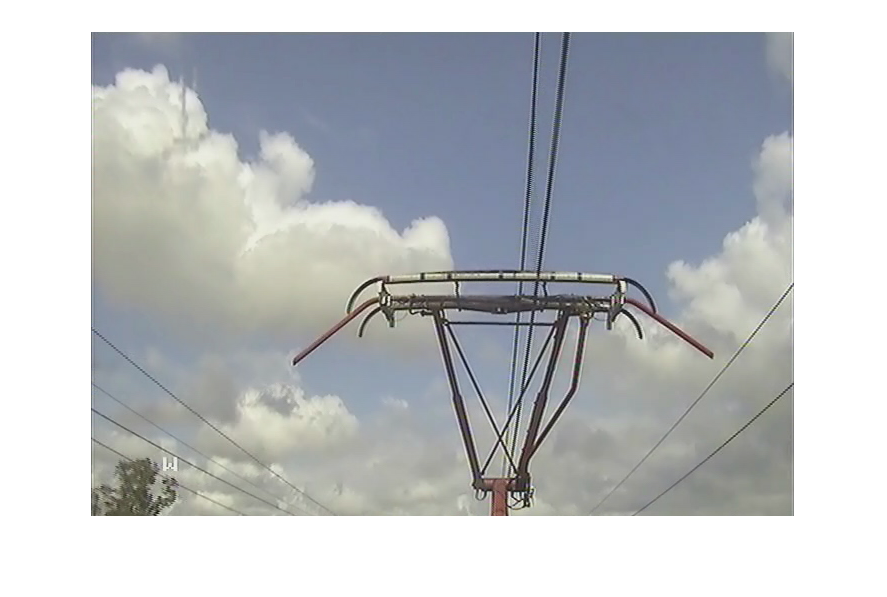

aCroppedFrame = PantographVideoProcessor.cropFrame(aCurrentFrame);
imshow(aCroppedFrame);

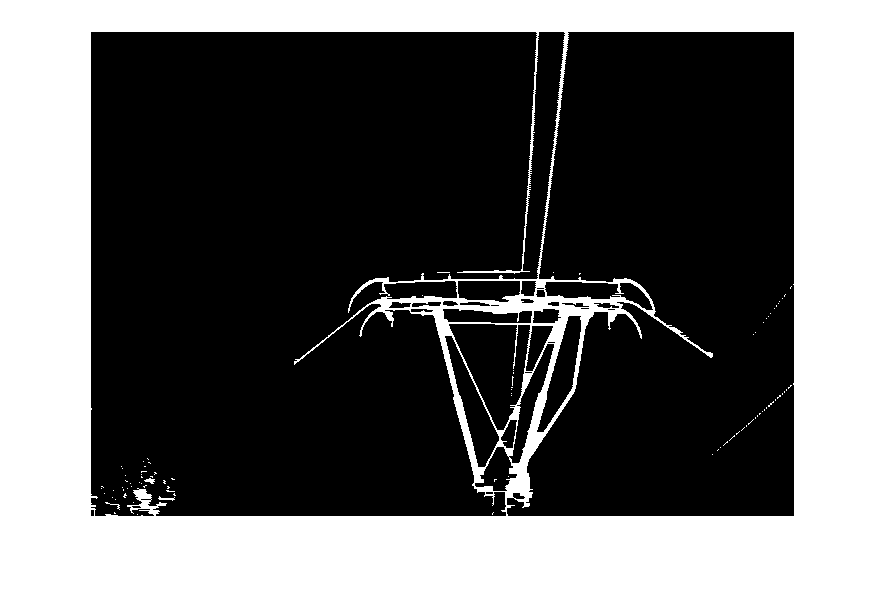

%Threshold image to outline pantograph
binarizedFrame = PantographVideoProcessor.thresholdFrame(aCroppedFrame, 0.3);

%Morphological processing
horizontalStrel = strel('line', 6, 0);
verticalStrel = strel('line', 12, 90);

edgedImage = imclose(binarizedFrame, horizontalStrel);
imshow(edgedImage);

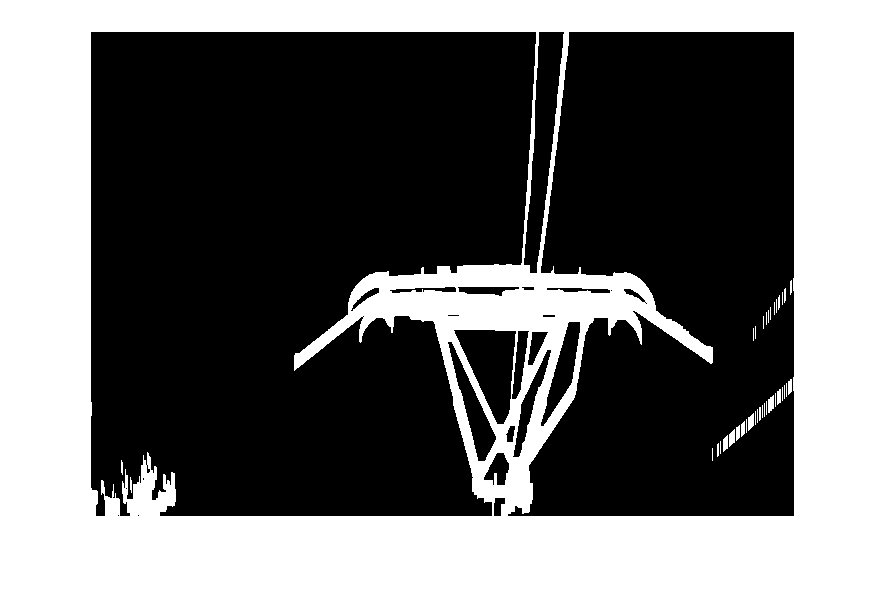


dilatedEdgeFrame = imdilate(edgedImage, verticalStrel);
imshow(dilatedEdgeFrame);

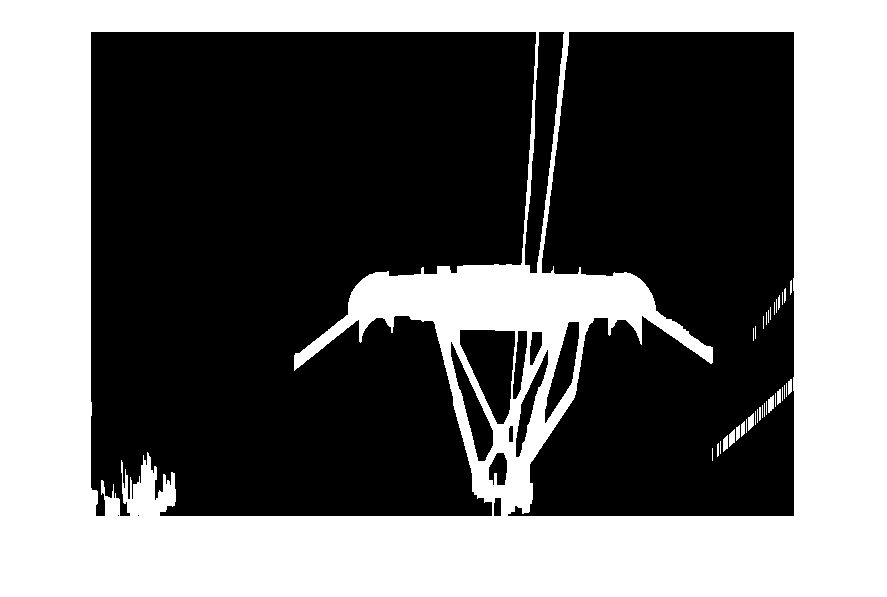


cleanedEdgeImage = imclose(dilatedEdgeFrame, verticalStrel);
imshow(cleanedEdgeImage);

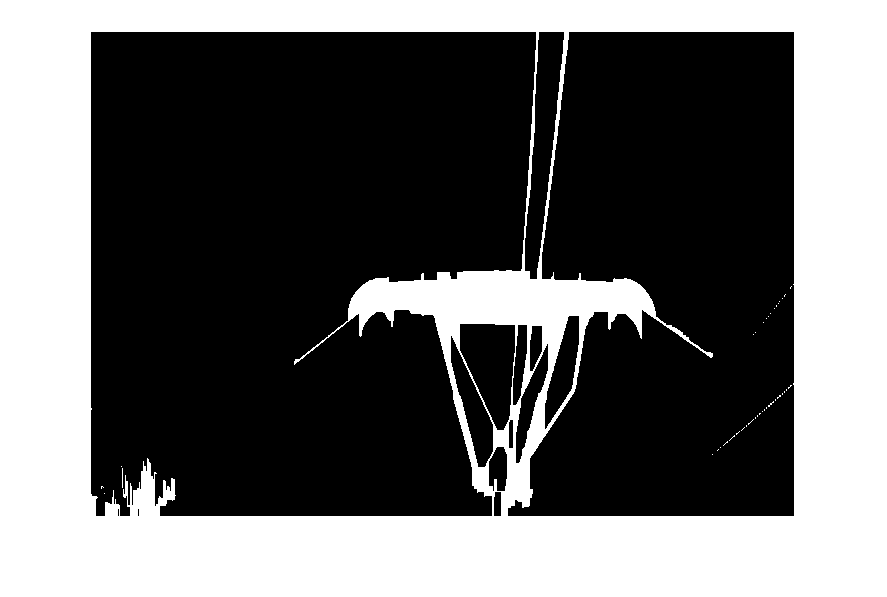


thinnedEdgeImage = imerode(cleanedEdgeImage, verticalStrel);
imshow(thinnedEdgeImage);


%Template matching 
correlation = xcorr2(thinnedEdgeImage, theTemplateImage);
[row, col] = find(correlation == max(max(correlation)), 1);
templatePosition = [row(1) col(1)];

%Temporal movement thresholding
% if (sum(self.theLastTemplatePos) == 0) || ...
%         (pdist2(self.theLastTemplatePos, templatePosition) < self.TEMPLATE_CHANGE_THRESHOLD)
%     self.theLastTemplatePos = templatePosition;
% else
%     templatePosition = self.theLastTemplatePos; 
% end

%Locate carbon brush relative to template
carbonBrush = [templatePosition + [-86 -327] ...
               templatePosition + [-86 -101]];

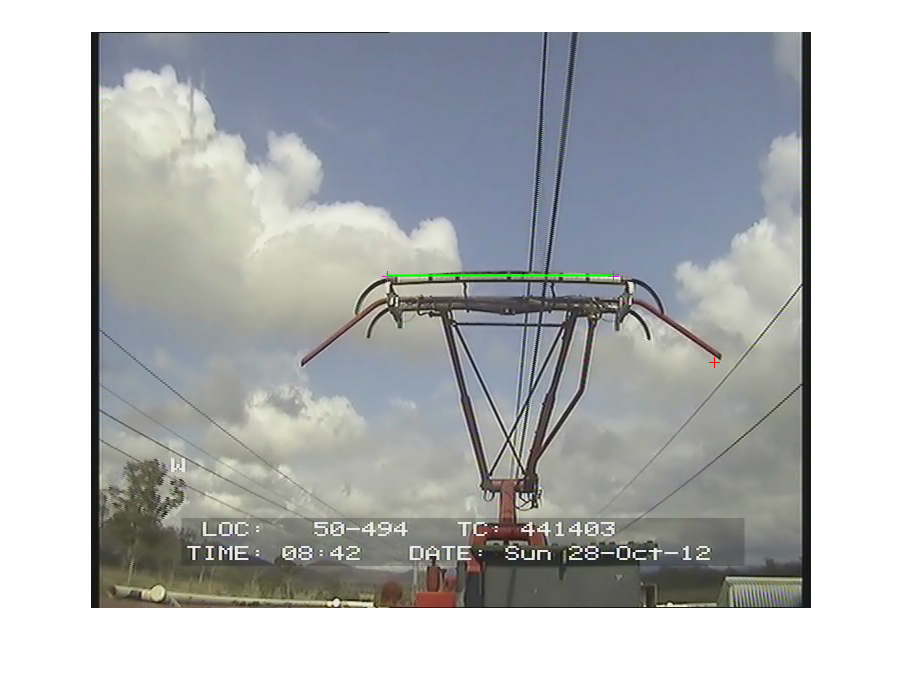

%%%%Mark the crossbar 
markTheSpot = insertMarker(aCurrentFrame, templatePosition([2, 1]),'Size',5,'Color','red');
markTheSpot = insertMarker(markTheSpot, carbonBrush([2, 1]),'Size',5,'Color','magenta');
markTheSpot = insertMarker(markTheSpot, carbonBrush([4, 3]),'Size',5,'Color','magenta');
markTheSpot = insertShape(markTheSpot, 'line', carbonBrush([2, 1, 4, 3]), 'LineWidth',2,'Color','green');
imshow(markTheSpot);

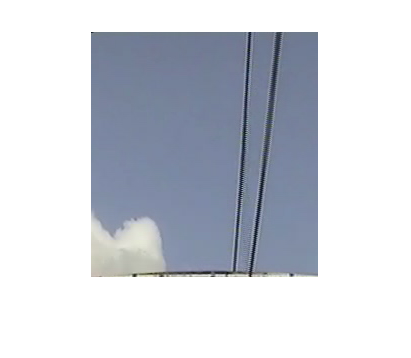

m = markTheSpot;

% figure()
% subplot(2,3,1); imshow(aCurrentFrame); title("Original Frame");
% subplot(2,3,2); imshow(aCroppedFrame); title("Cropped Frame");
% subplot(2,3,3); imshow(binarizedFrame); title("Binarized Image")
% subplot(2,3,4); imshow(thinnedEdgeImage); title("Morphological Image")
% subplot(2,3,5); imshow(correlation, [0 max(max(correlation))]); title("Cross Correlation Result")
% last = subplot(2,3,6); imshow(m); title(last, "Carbon Brush Localisation");
% hold off

%%%% Define power line search section as above crossbar 
verticalSearchSection = 1:carbonBrush(1);
horizontalSearchSection = (carbonBrush(2):carbonBrush(4));
searchSectionOffset = [horizontalSearchSection(1) 0];
aCurrentFrameSearchSection = aCurrentFrame(verticalSearchSection, horizontalSearchSection,:);
imshow(aCurrentFrameSearchSection);

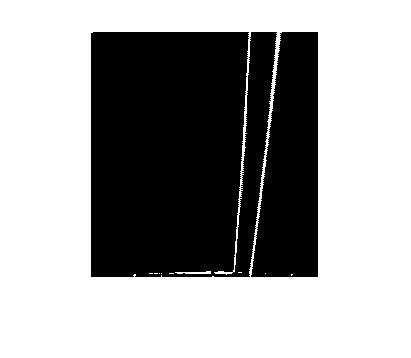


%%%%Create skeleton of powerlines in search section
linedSearchSection = ~imbinarize(rgb2gray(aCurrentFrameSearchSection), 0.3);
imshow(linedSearchSection);

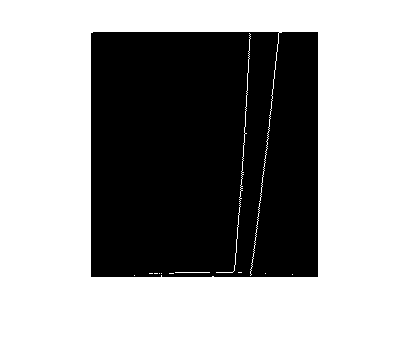


linedSearchSection = uint8(255 * bwskel(linedSearchSection));
imshow(linedSearchSection);


%Find & plot power lines
[houghMatrix, theta, rho] = hough(linedSearchSection);
lineDeviation = 15;       
houghMatrix = houghMatrix(:, 90 - lineDeviation:90 + lineDeviation);
theta = theta(:, 90 - lineDeviation:90 + lineDeviation);

P  = houghpeaks(houghMatrix, 10, 'NHoodSize', [15 15]);
lines = houghlines(linedSearchSection, theta, rho, P, 'MinLength', 0.5* carbonBrush(1));
      
%%%%Take two most prominent lines
if(size(lines, 1) > 2)
    lines = lines(1:2);
end
           
[angle, index] = max(abs(theta(P(:,2))));
lines = lines(index);
size(lines)

ans =      1     1


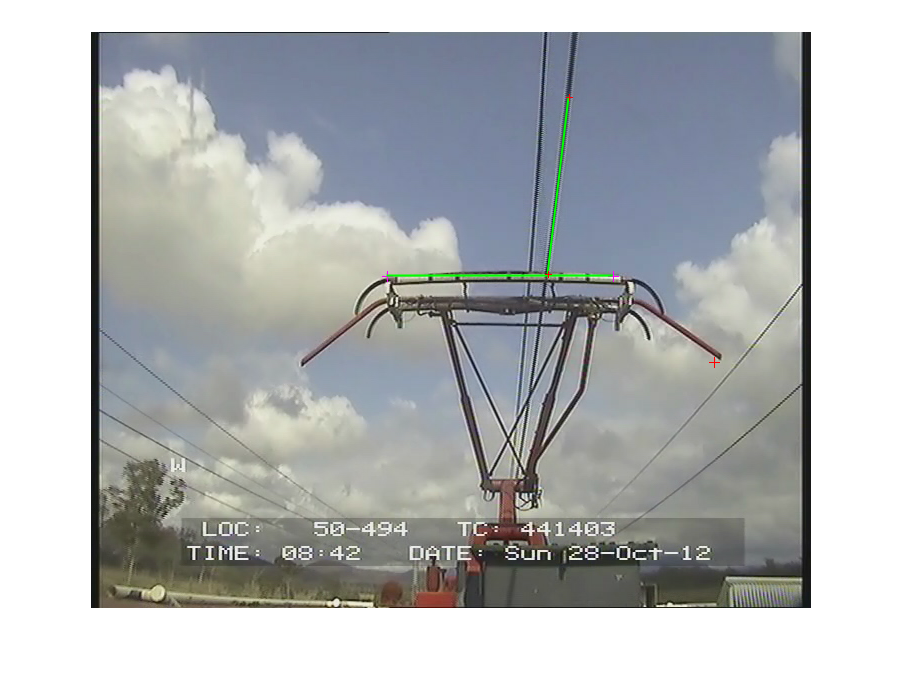


markTheSpot = plotLines(markTheSpot, lines, searchSectionOffset);
imshow(markTheSpot)

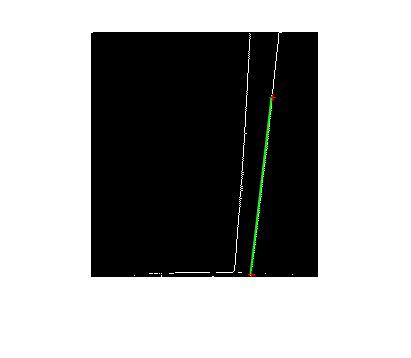

imshow(plotLines(linedSearchSection, lines));

%Find & plot intersection points
intersections = findIntersection(lines, carbonBrush, searchSectionOffset);
% if(size(intersections, 1) == 0)
%     self.theLeftIntersections(self.theFrameNumber) = self.theLeftIntersections(self.theFrameNumber - 1);
%     self.theRightIntersections(self.theFrameNumber) = self.theRightIntersections(self.theFrameNumber - 1);
% elseif(size(intersections, 1) == 1)
%     if(intersections(1,1) - self.theLeftIntersections(self.theFrameNumber - 1) < ...
%        intersections(1,1) - self.theRightIntersections(self.theFrameNumber - 1))
%         self.theLeftIntersections(self.theFrameNumber) = intersections(1,1) - carbonBrush(2);
%         self.theRightIntersections(self.theFrameNumber) = self.theRightIntersections(self.theFrameNumber - 1);
%     else
%         self.theRightIntersections(self.theFrameNumber) = intersections(1,1) - carbonBrush(2);
%         self.theLeftIntersections(self.theFrameNumber) = self.theLeftIntersections(self.theFrameNumber - 1);
%     end
% else
%     if(self.theFrameNumber == 1)
%         self.theLeftIntersections(1) = min(intersections(1,1), intersections(2,1)) - carbonBrush(2);
%         self.theRightIntersections(1) = max(intersections(1,1), intersections(2,1)) - carbonBrush(2);
%     else
%         [val, closestToLeft] = min(abs((self.theLeftIntersections(self.theFrameNumber - 1) + carbonBrush(2)) - intersections(:,1)));
%         [val, closestToRight] = min(abs((self.theRightIntersections(self.theFrameNumber - 1) + carbonBrush(2)) - intersections(:,1)));
%         self.theLeftIntersections(self.theFrameNumber) = intersections(closestToLeft,1) - carbonBrush(2);
%         self.theRightIntersections(self.theFrameNumber) = intersections(closestToRight,1) - carbonBrush(2);
%     end
% end
theOuterIntersections = intersections(1) - carbonBrush(2);
% theLeftIntersections = min(intersections(1,1), intersections(2,1)) - carbonBrush(2);
% theRightIntersections = max(intersections(1,1), intersections(2,1)) - carbonBrush(2);

% markTheSpot = insertMarker(markTheSpot, intersections, 'star', 'Size',8,'Color','blue');
imshow(markTheSpot);

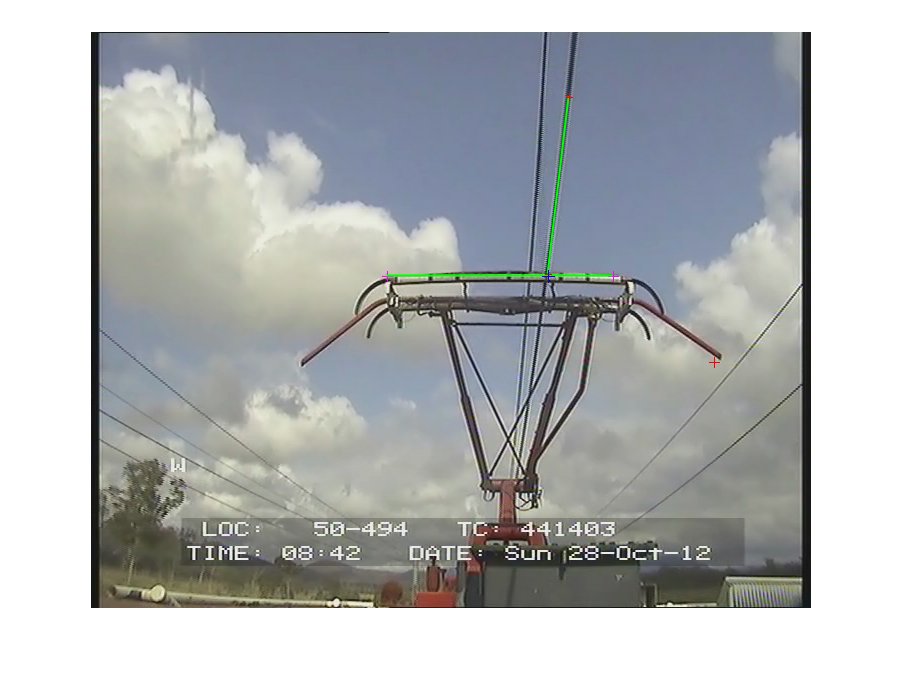

%  carbonBrushCentre = mean(carbonBrush([2,4])) - carbonBrush(2);
% if(abs(carbonBrushCentre - theLeftIntersections) > abs(carbonBrushCentre - theRightIntersections))
%     theTouchingIntersections = theLeftIntersections;
% else
%     theTouchingIntersections = theRightIntersections;
% end            

% markTheSpot = insertMarker(markTheSpot, [theLeftIntersections + carbonBrush(2) carbonBrush(1)], 'Size',4,'Color','magenta');
% markTheSpot = insertMarker(markTheSpot, [theRightIntersections + carbonBrush(2) carbonBrush(1)], 'Size',4,'Color','white');
markTheSpot = insertMarker(markTheSpot, [theOuterIntersections + carbonBrush(2) carbonBrush(1)], 'Size',6,'Color','blue');
imshow(markTheSpot);